[audio,fs] = audioread('samples/TURMER/raw/XC794897.wav');
audio = mono(audio);
audio = audio(1:10*fs);

plot(audio);

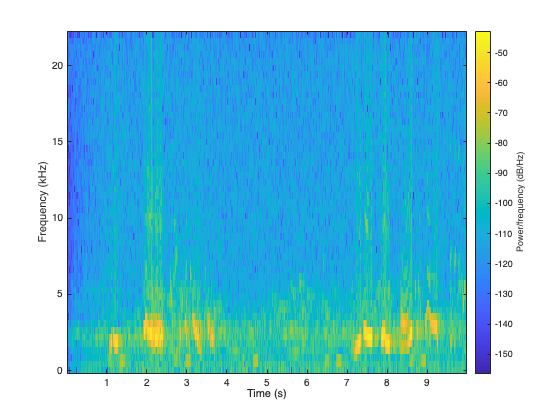

spectrogram(audio,100,80,100,fs,'yaxis')

filteredAudio = highpass(audio,500,fs);

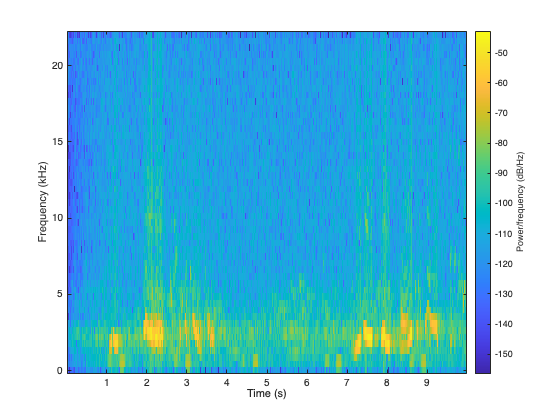

spectrogram(filteredAudio,100,80,100,fs,'yaxis')

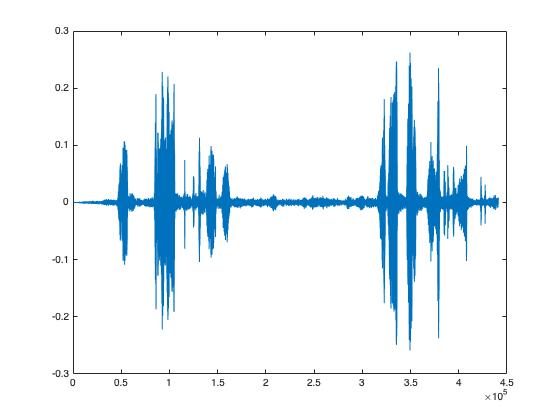

plot(audio)

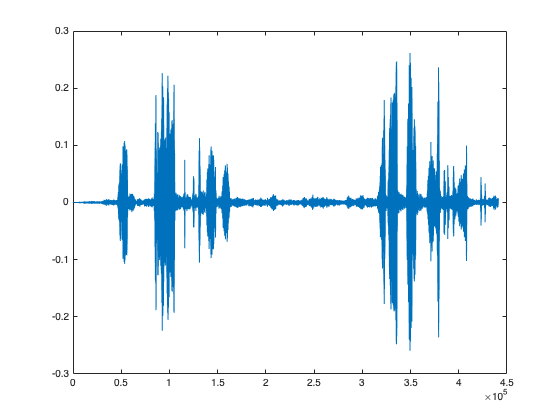

plot(filteredAudio)

fs = 2e3;
t = 0:1/fs:0.3-1/fs; fq = [-Inf -9:2]/12;
note = @(f,g) [1 1 1]*sin(2*pi*440*2.^[fq(g)-1 fq(g) fq(f)+1]'.*t);

mel = [5 3 1 3 5 5 5 0 3 3 3 0 5 8 8 0 5 3 1 3 5 5 5 5 3 3 5 3 1]+1;
acc = [5 0 8 0 5 0 5 5 3 0 3 3 5 0 8 8 5 0 8 0 5 5 5 0 3 3 5 0 1]+1;

song = [];
for kj = 1:length(mel)
    song = [song note(mel(kj),acc(kj)) zeros(1,0.01*fs)];
end
song = song/(max(abs(song))+0.1);

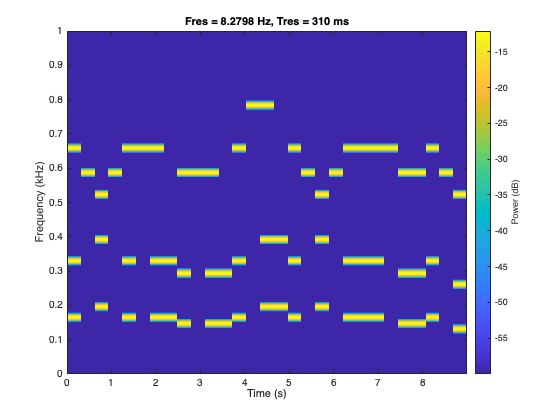

pspectrum(song,fs,"spectrogram",TimeResolution=0.31, ...
    OverlapPercent=0,MinThreshold=-60)

hong = highpass(song,450,fs);

sound(song,fs);
sound(hong,fs);

plot(song);